Mesh Plot

Design 89 Jmag Simulation

## MotorCAD 2 Jmag Modeling

            - Material Modeling

- 2D Modeling

              BEMF Calibration

- 3D Modeling

## JMAG 2 MotorCAD Modeling

## pde toolbox (from syre)

addpath(genpath(pwd))
addpath(genpath('Z:\Simulation\ACCESS2023\'))

## JMAG 2 other FEM Modeling

### Dxf Import

% addpath(genpath(pwd))
% %%
% TeslaSPlaidmshNotAll  % Make(Export m-file from unv(Jmag) in GMSH)
% % Z:\Simulation\ACCESS2023\HDEVOp4.m
% % % addpath(genpath('Z:\Thesis\00_Theory_Prof\JFT102'))
% % JFT102
% a.Color=[0.90,0.90,0.90]
% hold on
% A = area(msh)
% %% Periodic Model
% testDXFPath='Z:\Simulation\LabProj2023Evaluation\EqualFillFactor\A1_60\Design0089_A1B1_4ExportRotorPole.dxf'

### Mesh Define

## Define Mesh

HDEVdxfFilePath='Z:\pyleecan_GUI_version\20230623\HDEV_Model2Temp115PeriodicModel.dxf'
HDEVOp4
emagE = createpde("electromagnetic")
nodes=msh.POS(:,1:2)';
elements=msh.TRIANGLES(:,1:3)';
ax=gca
ax.GridAlpha = 0.05
geometryFromMesh(emagE,nodes,elements);
a=pdeplot(emagE.Mesh.Nodes, emagE.Mesh.Elements);
hold on
a.Color=[0.90,0.90,0.90]  % grey
pdegplot(emagE,"CellLabels","on","FaceAlpha",0.5)
area(emagE.Mesh,2);
testDXF=DXFtool(HDEVdxfFilePath)
centerfig()

#### Extract Stator Mesh

% elements=msh.TETS(:,1:4)'
elemIDs = findElements(emagE.Mesh,"radius",[0,0],141)
% a=emagE.Mesh.Elements(:,elemIDs)
elemIDsCell = arrayfun(@num2str, elemIDs, 'UniformOutput', false);
num_array = (1:1:17183);
% 숫자 배열을 문자열 cell 배열로 변환
str_cell = arrayfun(@num2str, num_array, 'UniformOutput', false);
[a,b,c]=findUniqueAndNonUniqueStrings(str_cell,elemIDsCell);

num_array = str2double(a);
stator.Mesh.Elements=emagE.Mesh.Elements(:,num_array);
statorE = createpde("electromagnetic");
% pdegplot(statorE,"EdgeLabels","on")
% stnodes=stator.Mesh.Nodes
stEle=stator.Mesh.Elements;
geometryFromMesh(statorE,emagE.Mesh.Nodes,stEle);

figure(2)
% a=pdemesh(statorE.Mesh.Nodes,statorE.Mesh.Elements)
a=pdeplot(statorE.Mesh.Nodes,statorE.Mesh.Elements)
a.Color=[0.90,0.90,0.90]  % grey
hold on
pdegplot(statorE,CellLabels="on")



### 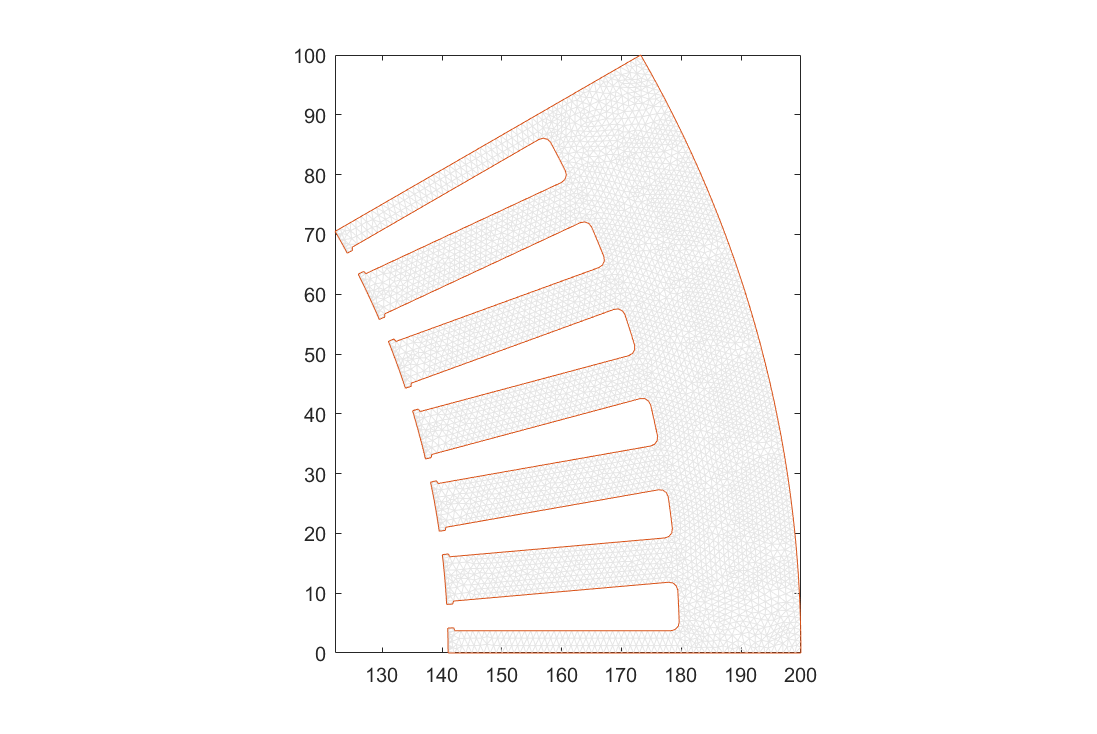

### Export JMAG Field Data

jmag = actxserver(strcat('Designer.Application.','222'));
Jgeom=actxserver(strcat('modeller','222'))
CurrentModel=app.GetCurrentModel()
app = modeller.get_application()

### Flux Loci Plot

hold on
Bx=readtable('Z:\Simulation\ACCESS2023\HDEVBx.csv');
By=readtable('Z:\Simulation\ACCESS2023\HDEVBy.csv');
Bx=readtable('Z:\Simulation\ACCESS2023\HDEVBxOP1.csv');
By=readtable('Z:\Simulation\ACCESS2023\HDEVByOP1.csv');
Bx.Properties.VariableNames(133) = "PosZ";
Bx.Properties.VariableNames(132) = "PosY";
Bx.Properties.VariableNames(131) = "PosX";
By.Properties.VariableNames(133) = "PosZ";
By.Properties.VariableNames(132) = "PosY";
By.Properties.VariableNames(131) = "PosX";
Bx.Properties.VariableNames(1) = "ElementID";
By.Properties.VariableNames(1) = "ElementID";
elementId=Bx.ElementID;
PosX=Bx.PosX;
PosY=By.PosY;
Bx = removevars(Bx, ["ElementID","PosX","PosY","PosZ"]);
By = removevars(By, ["ElementID","PosX","PosY","PosZ"]);
quiver(PosX,PosY,Br.Var2,Bt.Var2)
% Quiver Plot
figure(2)
hold on
quiver(PosX,PosY,Bx(:,2).Variables,By(:,2).Variables)
%%Loci Plot
BxMatrix=Bx.Variables;
ByMatrix=By.Variables;
for i=2:10:height(Bx)-1
    plot(PosX(i)+BxMatrix(i,:),PosY(i)+ByMatrix(i,:),'k')
    hold on
end
formatter_sci
title 'Flux Density Loci'
title 'Stator Core'
figure(2)
xlim([0 200]);
ylim([0 120]);
h = findobj('Type', 'figure');
for i=1:length(h)
b=h(i)
newPosition = [b.Position(1), b.Position(2), 1000, 500];
b.Position = newPosition; % Update the figure's position and size
end

export2PNGAll('Z:\Simulation')


## A Plot

% AzPath='D:\KDH\Thesis\HDEV\01_JMAG\Jproject\ASlice1JN.csv'
AzPath='D:\KDH\Thesis\HDEV\01_JMAG\Jproject\AOPx@4000rpm_lossOP4.csv'

Az=readtable(AzPath);
Az.Properties.VariableNames(133) = "PosZ";
Az.Properties.VariableNames(132) = "PosY";
Az.Properties.VariableNames(131) = "PosX";
Az.Properties.VariableNames(1) = "NodeID";

NodeID=Az.NodeID;
NodePosX=Az.PosX;
NodePosY=Az.PosY;
NodePosZ=Az.PosZ;


Az = removevars(Az, ["NodeID","PosX","PosY","PosZ"]);
Az.Properties.VariableUnits(1:end)={'Wb/m'}


figure(2)
a=pdeplot(statorE.Mesh.Nodes,statorE.Mesh.Elements)
a.Color=[0.90,0.90,0.90]  % grey
hold on
pdegplot(statorE,CellLabels="on")

hold on
quiver3(NodePosX,NodePosY,NodePosZ,zeros(length(NodePosZ),1),zeros(length(NodePosZ),1),Az(:,2).Variables);



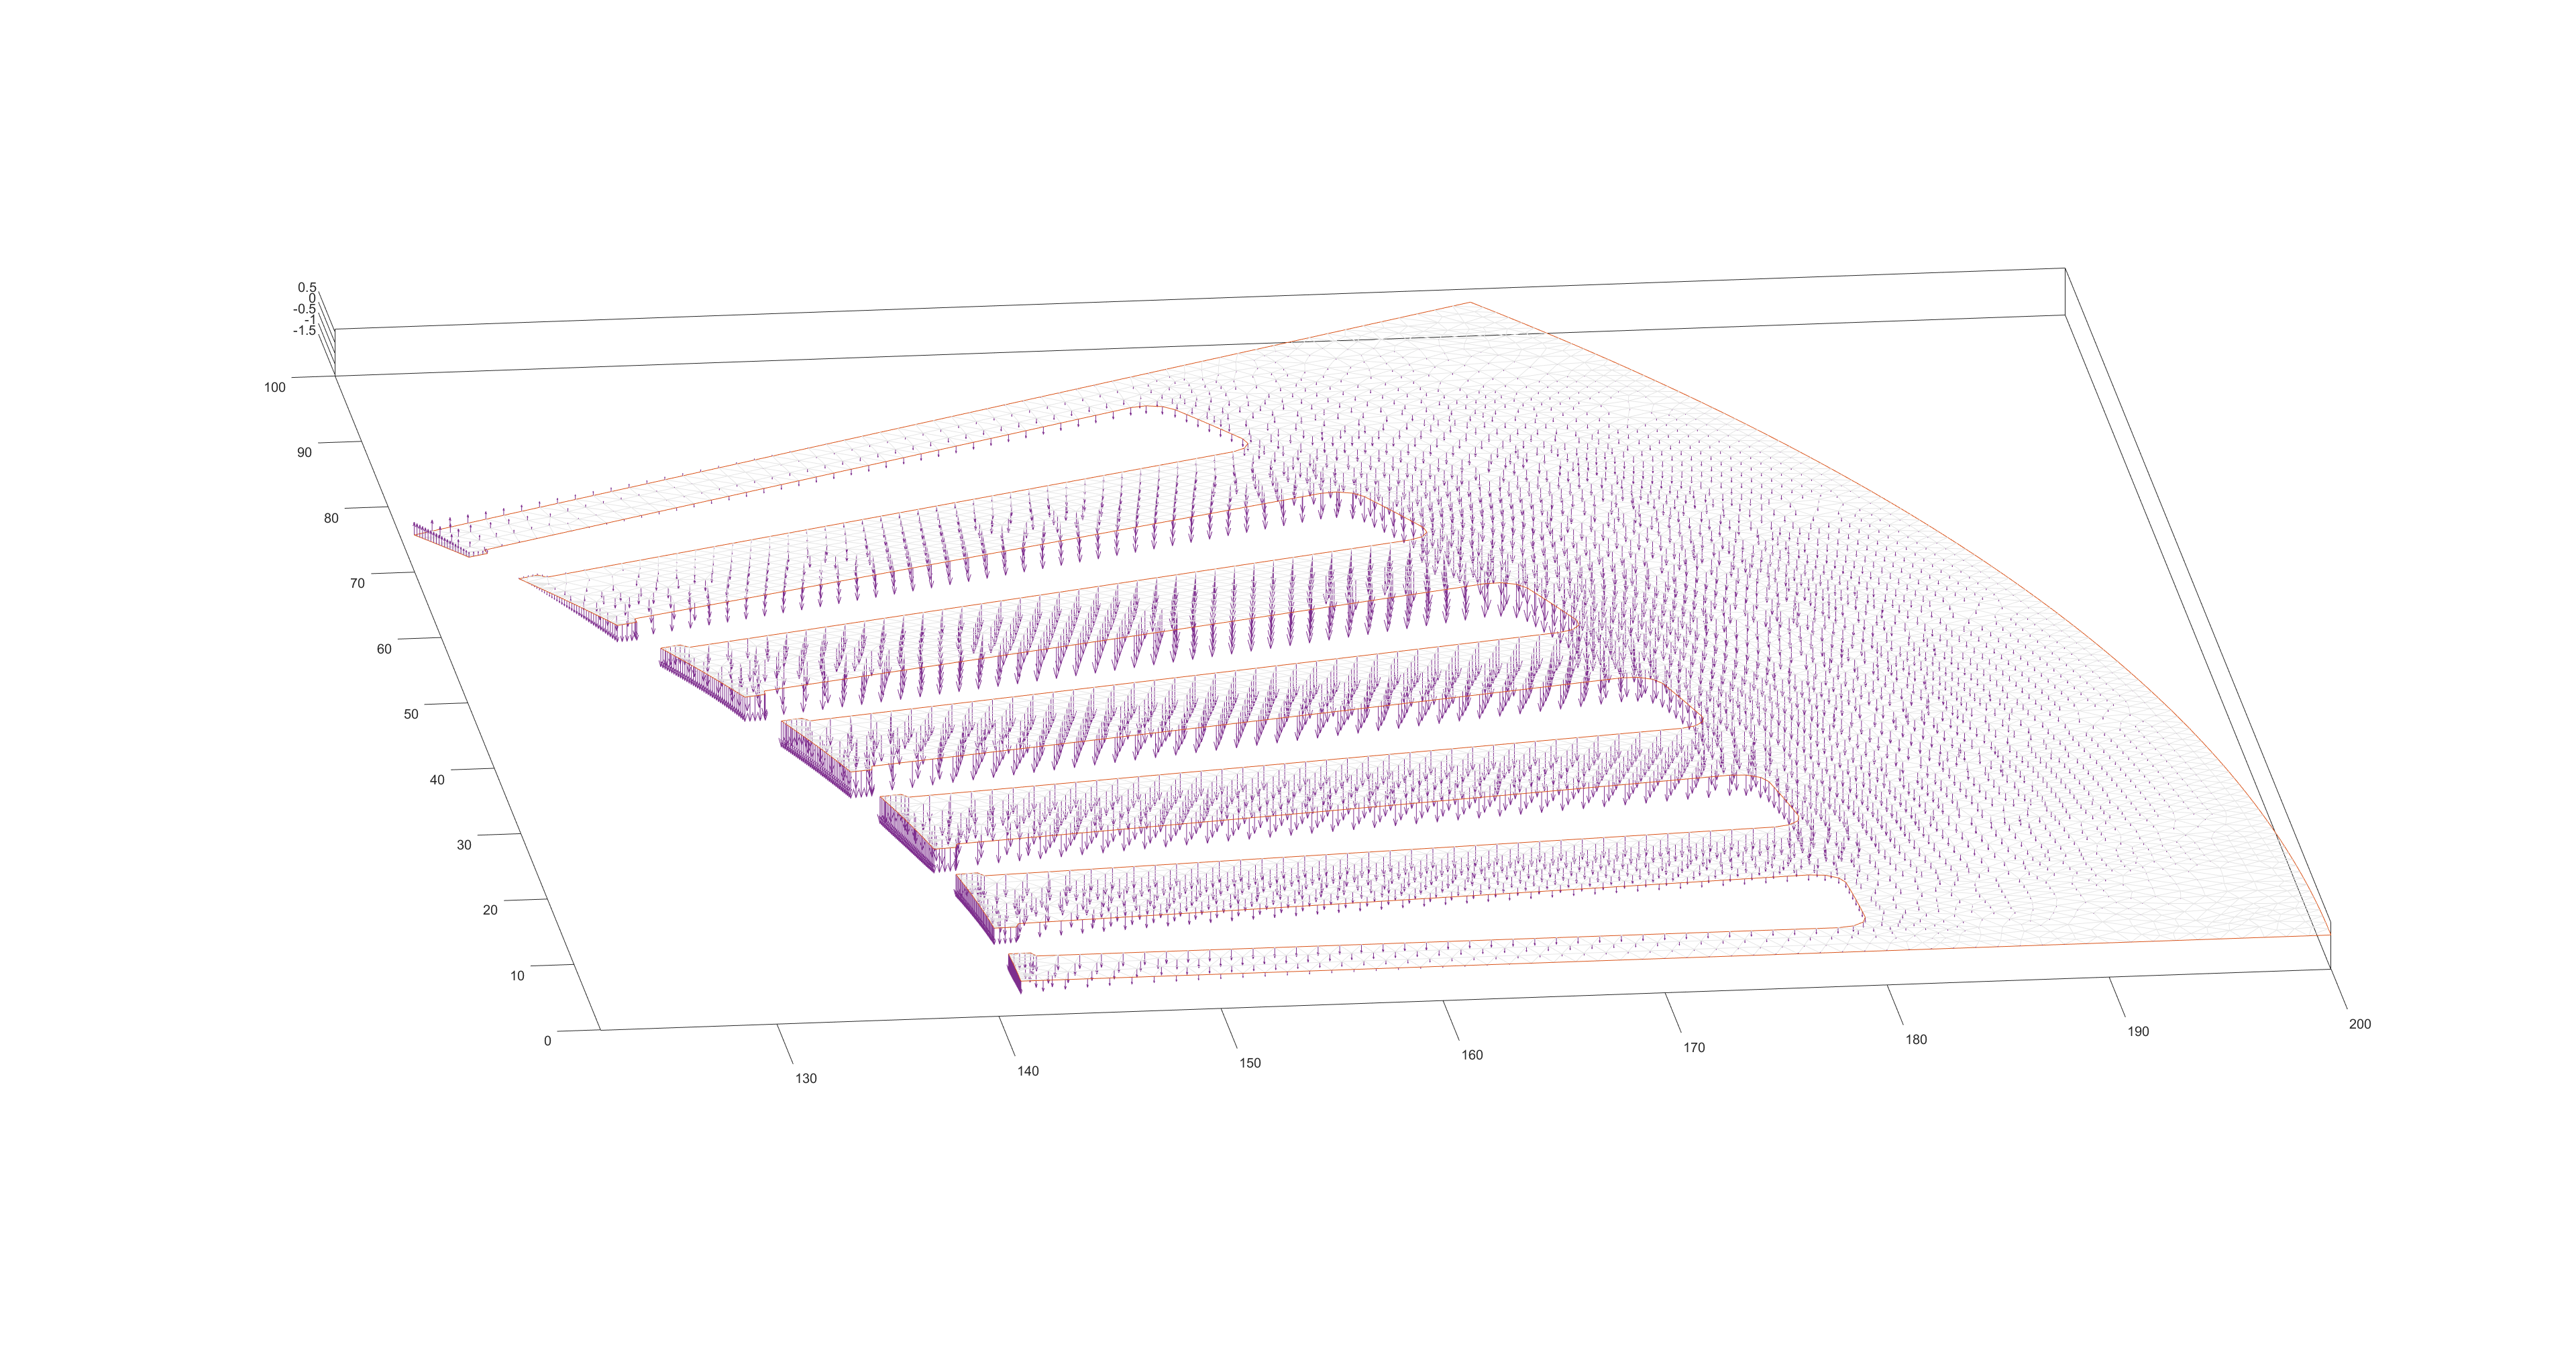

## B From A

- MotorProto

- MatrixFactory Format : 클래스 형태

continuumVariablePreProcessing

#### [TC] MotorProto


this.plot
solution.plot('A','Time',1);

this=solution.Matrices  %% DynamicMatrixFactory


        function [x, x_t, labels, text, nTimes] = continuumVariablePreProcessing(~, solver, dataType, dataPoints)
         	times = solver.Times;
            
            switch lower(dataType)
                case 'time'
                    x      = solver.X(:,dataPoints);
                    x_t    = solver.X_t(:,dataPoints);
                    labels = times(dataPoints);
                    nTimes = numel(dataPoints);
                    text   = 't = %0.4g';
                case 'harmonic'
                	x      = solver.X;
                    x_t    = solver.X_t;
                    labels = dataPoints;
                    nTimes = numel(times);
                    text   = 'h = %d';
                otherwise
                    x      = solver.X;
                    x_t    = solver.X_t;
                    labels = '';
                    nTimes = numel(times);
                    text   = '';
            end
        end



#### SMEKlib

drawFluxDensity>calculation_B

addpath(genpath('Z:\01_Codes_Projects\git_SMEKlib'))
HDEVMeshPDEtoolForm=statorE.Mesh;
[HDEVPetFor.p,HDEVPetFor.e,HDEVPetFor.t]=HDEVMeshPDEtoolForm.meshToPet();
HDEVPetFor.t(4,:)=[]
msh=HDEVPetFor

for i=1:1:1
A=Az{:,i}
figure(i)
drawFluxDensity(msh, A); 
end

triplot(HDEVPetFor.t', msh.p(1,:), msh.p(2,:));